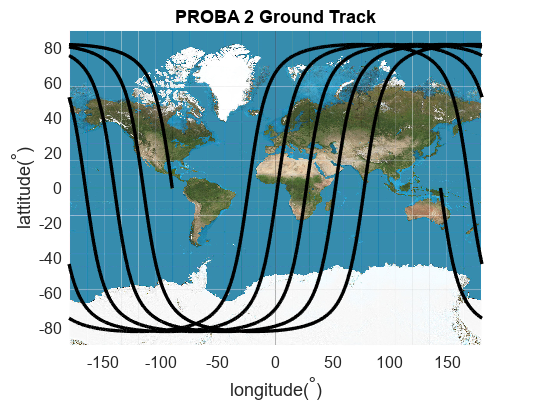

%The following code must be run in matlab live after calculating longitude
% and lattitude in PROBA2.m

figure
plot(longitude(1), lattitude(1),'k','LineWidth',2);
hold on


ylim([-90 90])
xlim([-180 180])
title('PROBA 2 Ground Track')
xlabel('longitude(^\circ)')
ylabel('lattitude(^\circ)')
    I = imread('map.png'); 
    image(xlim,-ylim,I);
dt = [diff(t, 500);0];
for i = 1:1000:length(longitude)
    hold on
    plot(longitude(1:i), lattitude(1:i),'k','LineWidth',2);
    drawnow;
    pause(1/1000);

    
end
    plot(longitude, lattitude,'k','LineWidth',2);

drawnow;